clearvars;
[data, label] = xlsread('Health index1.csv');
data = data(:, 1:15);
X = gpuArray(data)


X = <page truncated: showing [1:67, 1:15] of 470-by-15>

   1.0e+05 *

    0.0284    0.0586    0.2784    0.0741    0.0003    0.0134    0.1668    0.0547    0.0001    0.0002    0.0000    0.0004    0.0006         0    0.0010
    0.1289    0.0006    0.2504    0.0088    0.0008    0.0086    0.0000    0.0031         0    0.0004    0.0000    0.0004    0.0006         0    0.0009
    0.0282    0.1640    0.5630    0.0014    0.0026    0.0108    0.0021    0.0001    0.0219    0.0000    0.0000    0.0004    0.0005    0.0001    0.0009
    0.0110    0.0007    0.3752    0.0054    0.0018    0.0140    0.0001    0.0023         0    0.0009    0.0000    0.0003    0.0005    0.0001    0.0009
    0.0321    0.0357    0.4790    0.0016    0.0036    0.0213    0.0000    0.0004    0.0000    0.0000    0.0000    0.0004    0.0006    0.0000    0.0009
    0.1350    0.0034    0.3650    0.0315    0.0011    0.0098    0.0001    0.0123    0.0000    0.0000    0.0000    0.0004    0.0005    0.0001    0.0008
    0.1020    0.1190  

clear data

%% Step 1: Center the Data (Mean Subtraction)
mu = mean(X);
X_centered = X - mu;

fprintf('Centered Data:\n');

Centered Data:


disp(X_centered);

   1.0e+05 *

    0.0244   -0.0250   -0.1992    0.0733   -0.0021   -0.0047    0.1652    0.0539   -0.0008    0.0000   -0.0000    0.0001    0.0000   -0.0002    0.0007
    0.1248   -0.0830   -0.2272    0.0080   -0.0016   -0.0095   -0.0016    0.0022   -0.0009    0.0003   -0.0000    0.0001    0.0000   -0.0002    0.0006
    0.0242    0.0804    0.0854    0.0006    0.0001   -0.0074    0.0004   -0.0007    0.0210   -0.0002   -0.0000    0.0000   -0.0000   -0.0001    0.0006
    0.0069   -0.0829   -0.1024    0.0047   -0.0006   -0.0041   -0.0016    0.0015   -0.0009    0.0007    0.0000   -0.0001   -0.0000   -0.0001    0.0006
    0.0281   -0.0479    0.0014    0.0008    0.0012    0.0031   -0.0016   -0.0004   -0.0009   -0.0002   -0.0000    0.0001    0.0000   -0.0001    0.0006
    0.1310   -0.0801   -0.1126    0.0307   -0.0013   -0.0083   -0.0016    0.0115   -0.0009   -0.0002    0.0000   -0.0000   -0.0000   -0.0001    0.0005
    0.0980    0.0354   -0.1406    0.0049   -0.0016   -0.0121   -0.0016    0.0008

%% Step 2: PCA via SVD
[U, S, V] = svd(X_centered); % Economy-size SVD

% Principal Components (from V)
PC_svd = V;

% Projected Data (Scores)
scores_svd = X_centered * V;

% Explained Variance (Singular Values)
singular_values = diag(S);
explained_variance_svd = (singular_values.^2) / (size(X,1)-1);

fprintf('\n--- PCA via SVD ---\n');


--- PCA via SVD ---


fprintf('Principal Components (Columns of V):\n');

Principal Components (Columns of V):


disp(V);

    0.0149    0.0094    0.3638   -0.8094    0.4405    0.1006   -0.0838   -0.0048   -0.0333    0.0021    0.0007    0.0016    0.0003   -0.0011   -0.0003
   -0.8049    0.5931    0.0111   -0.0004    0.0023    0.0102    0.0003    0.0002   -0.0013    0.0002    0.0002    0.0001   -0.0000    0.0000   -0.0000
   -0.5931   -0.8046   -0.0138   -0.0262    0.0002    0.0008    0.0001    0.0010    0.0007   -0.0006   -0.0000    0.0001   -0.0001   -0.0001    0.0000
    0.0029    0.0023    0.0825   -0.1519   -0.1826    0.0889    0.7124    0.1200    0.6362   -0.0415    0.0183    0.0138    0.0004    0.0043    0.0002
    0.0003   -0.0010    0.0516    0.0302    0.0062   -0.0091   -0.0528    0.9890   -0.1241   -0.0016    0.0073   -0.0002   -0.0006    0.0028   -0.0013
   -0.0060   -0.0248    0.9061    0.4174    0.0199   -0.0040    0.0019   -0.0604   -0.0023   -0.0007   -0.0010    0.0010   -0.0000   -0.0008   -0.0004
    0.0042    0.0050    0.1820   -0.3536   -0.8660    0.0294   -0.3007   -0.0117   -0.0217    

fprintf('Singular Values:\n');

Singular Values:


disp(singular_values');

   1.0e+05 *

    3.1676    2.8750    0.4883    0.4644    0.2492    0.1252    0.0644    0.0426    0.0212    0.0101    0.0036    0.0027    0.0014    0.0013    0.0010



fprintf('Explained Variance:\n');

Explained Variance:


disp(explained_variance_svd');

   1.0e+08 *

    2.1394    1.7624    0.0508    0.0460    0.0132    0.0033    0.0009    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000




%% Step 3: PCA via Covariance Matrix
C = cov(X_centered); % Covariance matrix

[V_cov, D] = eig(C); % Eigenvectors and eigenvalues
[D_sorted, idx] = sort(diag(D), 'descend'); % Sort eigenvalues
V_cov = V_cov(:, idx); % Sort eigenvectors

% Projected Data (Scores)
scores_cov = X_centered * V_cov;

% Explained Variance (Eigenvalues)
explained_variance_cov = D_sorted / sum(D_sorted);

fprintf('\n--- PCA via Covariance Method ---\n');


--- PCA via Covariance Method ---


fprintf('Eigenvalues (D):\n');

Eigenvalues (D):


disp(D_sorted');

   1.0e+08 *

    2.1394    1.7624    0.0508    0.0460    0.0132    0.0033    0.0009    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



fprintf('Principal Components (Columns of V_cov):\n');

Principal Components (Columns of V_cov):


disp(V_cov);

   -0.0149    0.0094   -0.3638    0.8094    0.4405   -0.1006   -0.0838   -0.0048   -0.0333    0.0021   -0.0007    0.0016   -0.0003   -0.0011   -0.0003
    0.8049    0.5931   -0.0111    0.0004    0.0023   -0.0102    0.0003    0.0002   -0.0013    0.0002   -0.0002    0.0001    0.0000    0.0000   -0.0000
    0.5931   -0.8046    0.0138    0.0262    0.0002   -0.0008    0.0001    0.0010    0.0007   -0.0006    0.0000    0.0001    0.0001   -0.0001    0.0000
   -0.0029    0.0023   -0.0825    0.1519   -0.1826   -0.0889    0.7124    0.1200    0.6362   -0.0415   -0.0183    0.0138   -0.0004    0.0043    0.0002
   -0.0003   -0.0010   -0.0516   -0.0302    0.0062    0.0091   -0.0528    0.9890   -0.1241   -0.0016   -0.0073   -0.0002    0.0006    0.0028   -0.0013
    0.0060   -0.0248   -0.9061   -0.4174    0.0199    0.0040    0.0019   -0.0604   -0.0023   -0.0007    0.0010    0.0010    0.0000   -0.0008   -0.0004
   -0.0042    0.0050   -0.1820    0.3536   -0.8660   -0.0294   -0.3007   -0.0117   -0.0217    

fprintf('Explained Variance:\n');

Explained Variance:


disp(explained_variance_cov');

    0.5326    0.4388    0.0127    0.0114    0.0033    0.0008    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



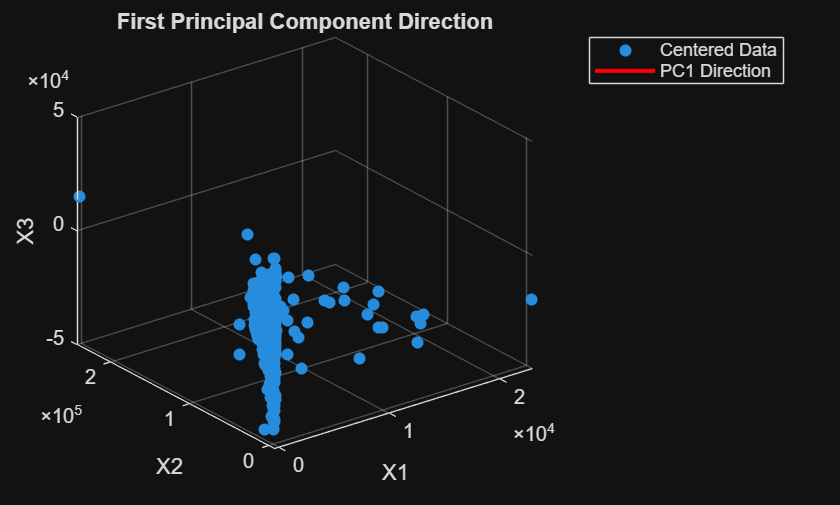


%% Step 4: Plot the First Principal Component
figure;
scatter3(X_centered(:,1), X_centered(:,2), X_centered(:,3), 'filled');
hold on;

% Plot the first PC direction
PC1 = V(:,1); % From SVD (same as V_cov(:,1))
t = linspace(-10,10,100);
line_x = mu(1) + t * PC1(1);
line_y = mu(2) + t * PC1(2);
line_z = mu(3) + t * PC1(3);
plot3(line_x, line_y, line_z, 'r', 'LineWidth', 2);

xlabel('X1'); ylabel('X2'); zlabel('X3');
title('First Principal Component Direction');
grid on;
legend('Centered Data', 'PC1 Direction');